% define superclusters based on the clustering results
% Author: Chang Lu
% luchang4104@gmail.com

clear all

% you can put your data folder under 'data' 
currentFolder = pwd;

% datapath = [currentFolder,filesep,'data',filesep,'mix with cd163'];
% or set you own path( replace the sentence above to the example below):
% datapath = '/Users/changlu/DATA/OLIVIA/30 clusters CDK5 New'; % your own data path
datapath = '/Volumes/ChangLu/Laura/LK7newfoldersforchang';

addpath(genpath('fun'));

files=dir(fullfile(datapath));
isub = [files(:).isdir];
fileNames={files(isub).name}';
fileNames(ismember(fileNames,{'.','..','results'})) = [];


##  load data

% the mat files in the datapath
clusterfilename = 'cosine_kmedoids_k=40';
datamatname = 'cellmarker_rescale_intergration_t=2';

load([datapath,filesep,clusterfilename]); % clustering results
load([datapath,filesep, datamatname]);

## result save path

directory = [datapath,filesep,'results',filesep, datamatname, clusterfilename,filesep];
if ~exist(directory,'dir')
    mkdir(directory);
end

## Read supercluster csv

% read the superclusters' colors (here is 'rescale_t=2_supercluster.csv' (output of 'reclustering.mlx')) you saved
TT = readtable([datapath,filesep, 'rescale_t=2_supercluster.csv']);
T = table(labels);
T = join(T,TT,"Keys","labels");

TT(:,3:5)

ans = 40×3 table
    supercolors_1    supercolors_2    supercolors_3
    _____________    _____________    _____________

       0.56863          0.24706          0.17255   
       0.36863          0.62353          0.66275   
       0.80392          0.80784          0.63922   
       0.85882          0.27059          0.19608   
       0.56863          0.24706          0.17255   
       0.66667          0.58824          0.26275   
       0.85882          0.27059          0.19608   
       0.56078          0.21569              0.4   
       0.78824          0.53725          0.56863   
       0.41569          0.83529          0.29412   
       0.44314          0.26667              0.8   
       0.69412           0.7098          0.84314   
       0.30588          0.14118          0.16471   
        0.7451           0.8549          0.29412   
       0.85882          0.27059          0.19608

## visualization: MST

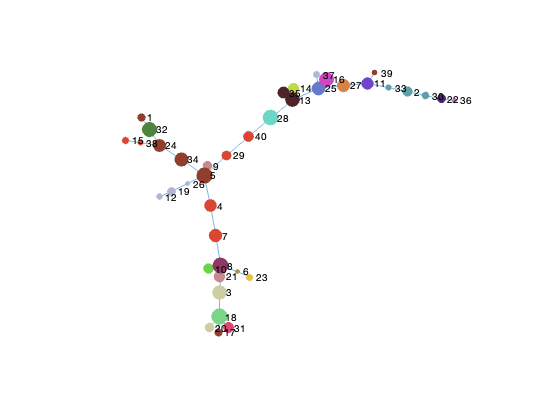

h = draw_mst_new(labels,centers,'cosine',TT{:,3:5}, 'F');
print(gcf,'-dpng',[directory,'SuperClu-MST.jpg']);

## cell count

%% number of cell per cluster in each folder
bindtable = [labels,T.superlabels,foldername];
for i = 1:length(nuancename)
   tablei =  tabulate(bindtable(bindtable(:,3)==nuancename{i},2));
   A = array2table(tablei);
   A.Properties.VariableNames(1:3) = {'Cluster','count','percentage'};
   filename = fullfile(directory, 'cell_count_persupercluster_in_each_folder.xlsx');
   writetable(A,filename,'Sheet',nuancename{i});
end


## H&E visualization

clus=unique(T.superlabels');
color = [255,0,0];
plaquesname= nuancename;
for cl=1:length(clus)
    c_name = clus{cl};
    for i= 1:length(plaquesname)
        draw_several_clusters_on_allimgsinglefig(T.superlabels,plaquesname{i},nuancename,{cl},mix_pos,begin_idx,datapath,directory,color,c_name);
    end
end


## polar histogram

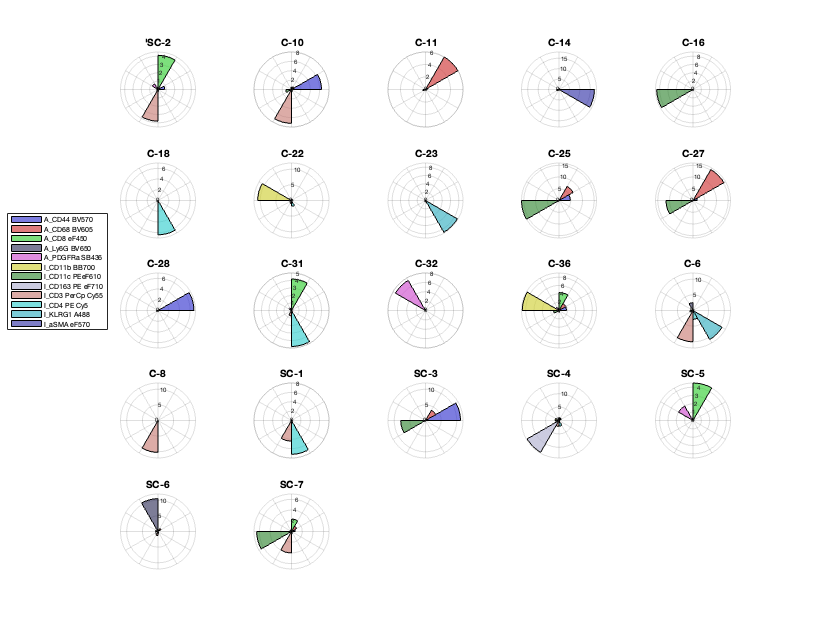

filename = [directory,clusterfilename,'histogram'];
supercenters = getCenters(T.superlabels,norm_inten);
draw_Polar_fig(T.superlabels,supercenters,biomarkername,filename);

## inich analysis

% r : We only consider neighbors within a radius of r （pixels， The default value is 50）
% k ：kmeans clustering for the niches (The default value is 100)
[inich_mat, inchcluster, inchcenter, neigh_adj_cell]=inichesanalysis( T.superlabels ,nuancename, mix_pos,begin_idx, 50, 100, datapath);

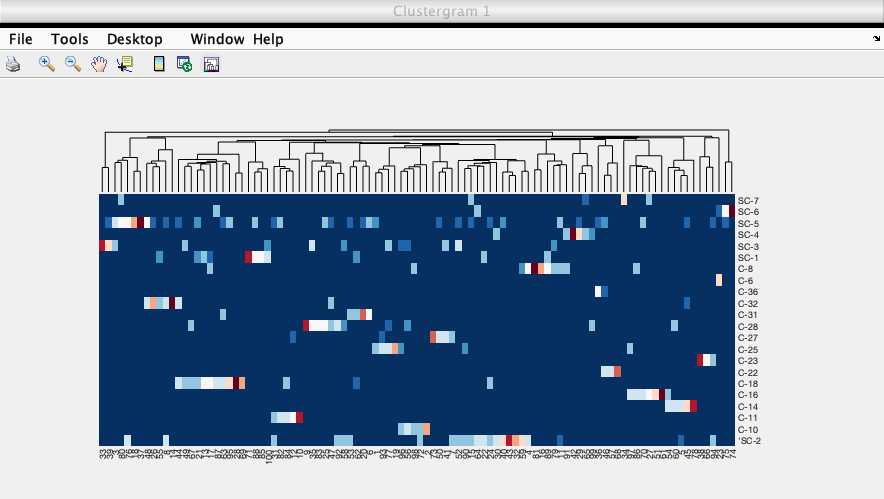

uniclu = unique(inchcluster);
CGObject=clustergram(inchcenter','cluster',2,'RowLabels',unique(T.superlabels) , 'ColumnLabels', uniclu(2:(size(inchcenter,1)+1)), 'Colormap',redbluecmap,'Symmetric',false);

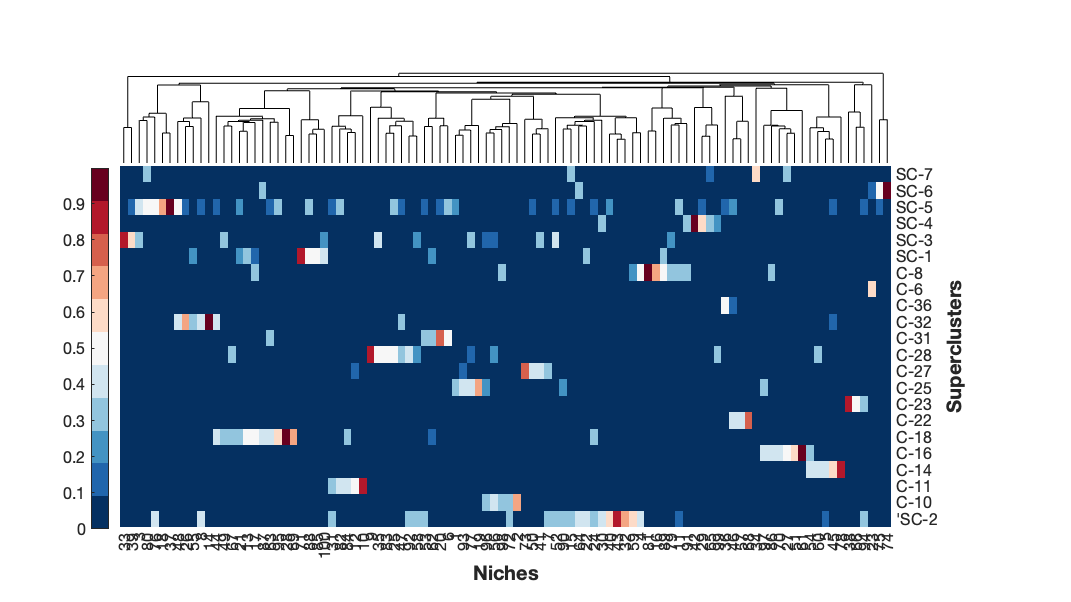

fig = figure;
scrsz = get(0,'ScreenSize'); set(gcf,'Position',scrsz);
h1=plot(CGObject,fig);
h1.FontSize = 16;
colorbar(h1,'manual','Position',[0.085 0.121 0.017 0.6],'FontSize',16);
addXLabel(CGObject,'Niches','FontSize',20,'FontWeight','bold');
addYLabel(CGObject, 'Superclusters','FontSize',20,'FontWeight','bold');

% title([clu_meth_name,'  inich_heatmap']);
% directory = [newfolder,'\results\',fordername,filesep,meth_name,filesep];
% if ~exist(directory,'dir')
%     mkdir(directory);
% end
% savefig(CGObject,[directory,'inich_heatmap.fig']);
% saveas(gcf,[directory,'inich_heatmap.jpg']);

writetable(array2table(inich_mat, 'VariableNames', unique(T.superlabels)), fullfile(directory,'inches.xlsx'), "Sheet", 'inich_mat')
writematrix(inchcluster, fullfile(directory,'inches.xlsx'), "Sheet", 'inchecluster','WriteMode','append');
writematrix(foldername, fullfile(directory,'inches.xlsx'), "Sheet", 'folder','WriteMode','append'); 
writetable(T, fullfile(directory,'inches.xlsx'), "Sheet", 'supercluster','WriteMode','append');